#  ENME462 Studio 7 Assessing Stability Using Routh-Hurwitz Method 

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM; Section 0103 F 10:00AM - 11:50AM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

## **Stability of Linear Systems**

A linear time-invariant(LTI) system with the following transfer function 


$$G(s)=\frac{num(s)}{den(s)}=\frac{\prod_{i=0}^m(s-z_i)}{\prod_{i=0}^n(s-p_k)}$$


is  

1. **Stable and BIBO stable** if and only if  all of its poles $p_k$ statisfy


$$\text{Re}(p_k)<0, k=1,...,n$$


2. **Marginally Stable** if 


$$\text{Re}(p_k)\leq0, k=1,...,n$$


and poles on the $j\omega$-axis have multiplicity =1

3. **Not BIBO stable** if $G(s)$ has any pole on the $j\omega-$axis.

4. **Unstable** if $G(s)$ has

    a. one or more poles in the right half plane (RHP)

    b. poles on the $j\omega$-axis with multiplicity > 1

**Example 1.**  Determine the stability of the closed-loop transfer function


$$T(s)=\frac{10}{s^5+2s^4+3s^3+6s^2+5s+3}$$


a) Construct the Routh table for the closed-loop transfer function above and study the stability of the closed loop system.

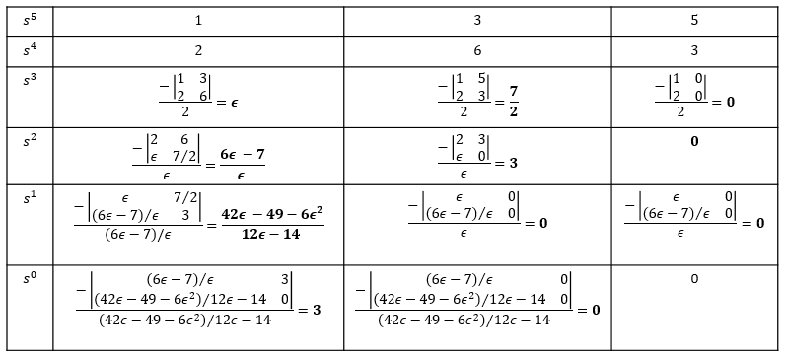

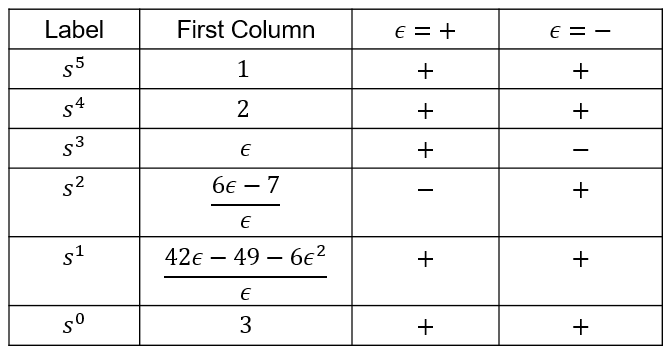

b)Use MATLAB commands to verify the obtained answer.

%% Method 1: define the coefficient array of Denominator 
den = [1, 2, 3, 6, 5, 3];
roots(den)

ans =    0.3429 + 1.5083i
   0.3429 - 1.5083i
  -1.6681 + 0.0000i
  -0.5088 + 0.7020i
  -0.5088 - 0.7020i


%% Method 2: MATLAB control toolbox
num =10;
T = tf(num,den)


T =
 
                   10
  -------------------------------------
  s^5 + 2 s^4 + 3 s^3 + 6 s^2 + 5 s + 3
 
Continuous-time transfer function.



pole(T)

ans =    0.3429 + 1.5083i
   0.3429 - 1.5083i
  -1.6681 + 0.0000i
  -0.5088 + 0.7020i
  -0.5088 - 0.7020i


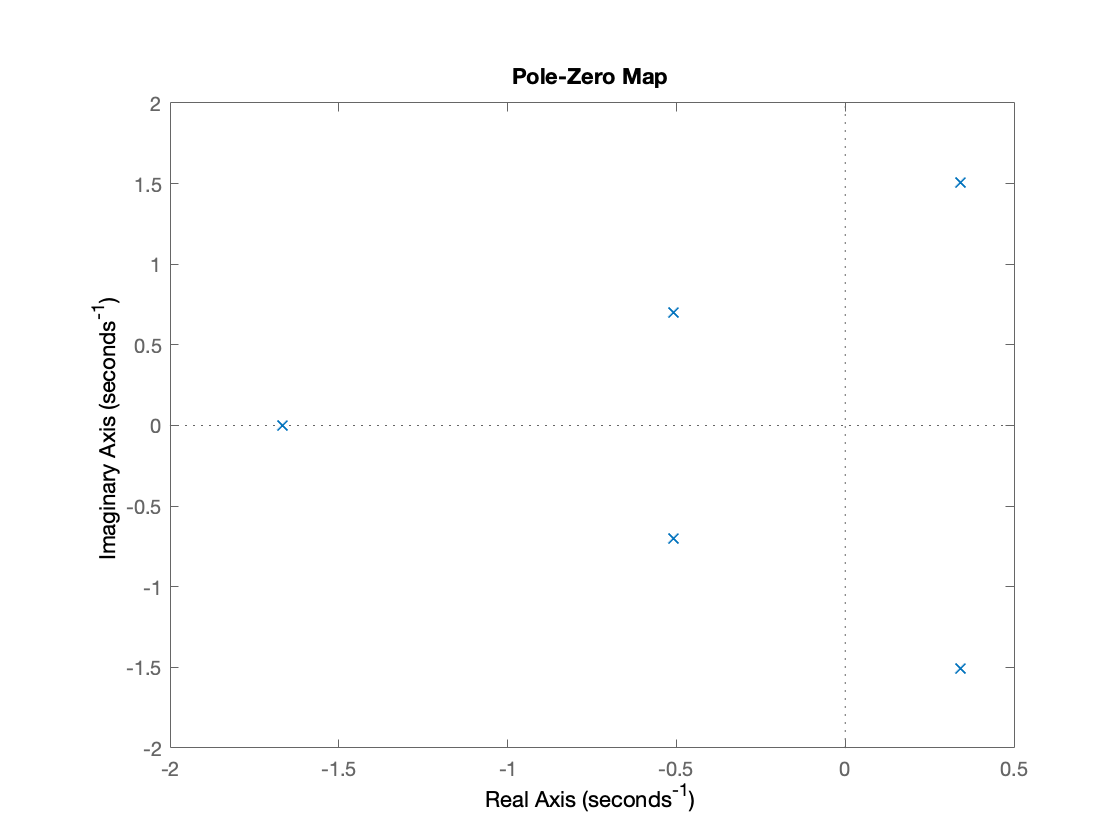

pzmap(T)

 c) Routh array using symbolic computation (ch6sp1)

'(ch6sp1)  Example 6.2'       % Display label.

ans = '(ch6sp1)  Example 6.2'

% -det([si() si();sj() sj()])/sj()
                              % Template for use in each cell.
syms e                        % Construct a symbolic object for 
                              % epsilon.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
s5=[1 3 5 0 0];               % Create s^5 row of Routh table.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
s4=[2 6 3 0 0];               % Create s^4 row of Routh table.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if -det([s5(1) s5(2);s4(1) s4(2)])/s4(1)==0
	s3=[e...
 -det([s5(1) s5(3);s4(1) s4(3)])/s4(1)   0   0];
                              % Create s^3 row of Routh table 
                              % if 1st element is 0.
else
    s3=[-det([s5(1) s5(2);s4(1) s4(2)])/s4(1)...
 -det([s5(1) s5(3);s4(1) s4(3)])/s4(1)   0   0];
                              % Create s^3 row of Routh table 
                              % if 1st element is not zero.
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if -det([s4(1) s4(2);s3(1) s3(2)])/s3(1)==0
	s2=[e ... 
 -det([s4(1) s4(3);s3(1) s3(3)])/s3(1)   0   0];
                              % Create s^2 row of Routh table 
                              % if 1st element is 0.
else	
    s2=[-det([s4(1) s4(2);s3(1) s3(2)])/s3(1) ... 
 -det([s4(1) s4(3);s3(1) s3(3)])/s3(1)   0   0];
                              % Create s^2 row of Routh table 
                              % if 1st element is not zero.
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if -det([s3(1) s3(2);s2(1) s2(2)])/s2(1)==0
	s1=[e ... 
 -det([s3(1) s3(3);s2(1) s2(3)])/s2(1)   0   0];
                              % Create s^1 row of Routh table 
                              % if 1st element is 0.
else
s1=[-det([s3(1) s3(2);s2(1) s2(2)])/s2(1) ... 
 -det([s3(1) s3(3);s2(1) s2(3)])/s2(1)   0   0];
                              % Create s^1 row of Routh table 
                              % if 1st element is not zero
end							  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%							  
s0=[-det([s2(1) s2(2);s1(1) s1(2)])/s1(1) ... 
 -det([s2(1) s2(3);s1(1) s1(3)])/s1(1)   0   0];
                              % Create s^0 row of Routh table.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
's5'                          % Display label. 

ans = 's5'

s5=sym(s5);                   % Convert s5 to a symbolic object.
s5=simplify(s5);              % Simplify terms in s^5 row.
pretty(s5)                    % Pretty print s^5 row.

(1, 3, 5, 0, 0)



's4'                          % Display label. 

ans = 's4'

s4=sym(s4);                   % Convert s4 to a symbolic object.
s4=simplify(s4);              % Simplify terms in s^4 row.
pretty(s4)                    % Pretty print s^4 row.

(2, 6, 3, 0, 0)



's3'                          % Display label. 

ans = 's3'

s3=sym(s3);                   % Convert s3 to a symbolic object.
s3=simplify(s3);              % Simplify terms in s^3 row.
pretty(s3)                    % Pretty print s^3 row.

/    7       \
| e, -, 0, 0 |
\    2       /



's2'                          % Display label.

ans = 's2'

s2=sym(s2);                   % Convert s2 to a symbolic object.
s2=simplify(s2);              % Simplify terms in s^2 row.
pretty(s2)                    % Pretty print s^2 row.

/ 6 e - 7          \
| -------, 3, 0, 0 |
\    e             /



's1'                          % Display label.

ans = 's1'

s1=sym(s1);                   % Convert s1 to a symbolic object.
s1=simplify(s1);              % Simplify terms in s^1 row.
pretty(s1)                    % Pretty print s^1 row.

/      2                      \
|   6 e  - 42 e + 49          |
| - ----------------, 0, 0, 0 |
\      (6 e - 7) 2            /



's0'                          % Display label.

ans = 's0'

s0=sym(s0);                   % Convert s0 to a symbolic object.
s0=simplify(s0);              % Simplify terms in s^0 row.
pretty(s0)                    % Pretty print s^0 row.

(3, 0, 0, 0)



**Example 2.** It is possible to utilize the Routh array to design parameters or controller gain in the system, from the stability perspectives.

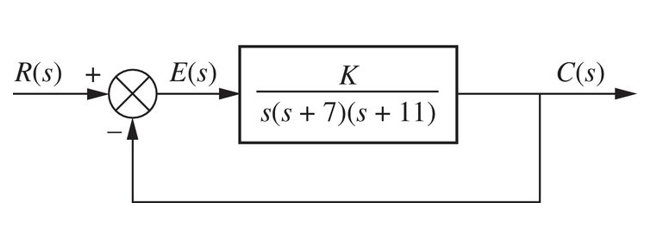

The closed loop transfer function as 


$$T(s)=\frac{K/\left(s\left(s+7\right)\left(s+11\right)\right)}{1+K/\left(s\left(s+7\right)\left(s+11\right)\right)}=\frac{K}{s^3+18s^2+77s+K}$$


Routh table

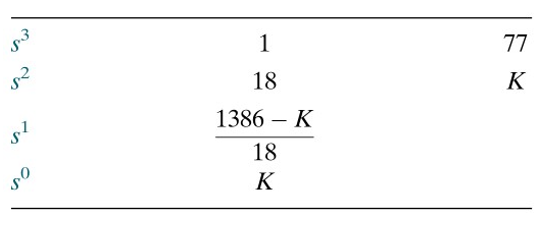

'(ch6p2) Example 6.9'               % Display label.

ans = '(ch6p2) Example 6.9'

K=[1:1:2000];                       % Define range of K from 1 to 2000 in 
                                    % steps of 1.
for n=1:length(K)                   % Set up length of DO LOOP to equal 
                                    % number of K values to be tested.
       dent=[1 18 77 K(n)];         % Define the denominator of T(s) for 
                                    % the nth value of K.
       poles=roots(dent);           % Find the poles for the nth value of 
                                    % K.
       r=real(poles);               % Form a vector containing the real 
                                    % parts of the poles for K(n).
             if max(r)>=0           % Test poles found for the nth value 
                                    % of K for a real value > or = 0.
                  poles             % Display first pole values where
                                    % there is a real part > or = 0.
                  K=K(n)            % Display corresponding value of K.
                  break             % Stop loop if rhp poles are found.
       end                          % End if. 
end                                 % End for.

poles =  -18.0025 + 0.0000i
   0.0012 + 8.7775i
   0.0012 - 8.7775i


K = 1387